clear;
clc;

addpath('D:\Matlab\Data');
addpath('D:\Matlab\SNCCE');
HSI_gt = importdata('Data\Botswana_gt.mat');
% HSI_gt = HSI_gt(1:1.5:end, 1:1.5:end);

img = importdata('D:\Matlab\SNCCE\Results_SNCCE\Botswana\kme.mat');

gt = HSI_gt(:);
gt = double(HSI_gt(:));
gt(gt == 0) = [];

% SalinasA
% gt(gt == 10) = 2;
% gt(gt == 11) = 3;
% gt(gt == 12) = 4;
% gt(gt == 13) = 5;
% gt(gt == 14) = 6;
% 
% img(img == 10) = 2;
% img(img == 11) = 3;
% img(img == 12) = 4;
% img(img == 13) = 5;
% img(img == 14) = 6;
% 
% SalinasA_map = [0, 0, 131;...
%                 0, 131, 255;...
%                 131, 255, 123;...
%                 3, 255, 251;...
%                 255, 251, 0;...
%                 255, 123, 0;...
%                 187, 0, 0];
% SalinasA_map = SalinasA_map ./ 255;

im = img(:);
im(im == 0) = [];

% symnmf, kmeans, fcm, finch, ssc, dbscan, fsfdp, sc, symnmfcce
[ARI, ~, ~, ~] = ari(gt, im)

ARI = 0.4365

[OA, Kappa, PA, UA] = calaccuracy(gt, im)

OA = 0.5172

Kappa = 0.4754

PA =     1.0000
         0
    0.6534
    0.5953
    0.7323
    0.3123
    0.6255
    0.0788
    0.8758
    0.6048


UA =     0.9677
         0
    0.9535
    0.4867
    0.5988
    0.2246
    0.4274
    0.1176
    0.4599
    0.7772


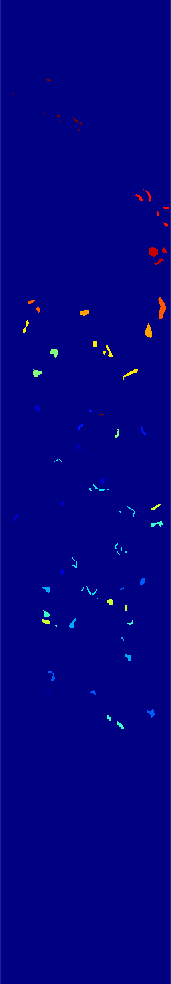

PA = roundn(PA, -4);
UA = roundn(UA, -4);
OA = roundn(OA, -4);
Kappa = roundn(Kappa, -4);
ARI = roundn(ARI, -4);
index = [OA; Kappa; ARI];

imshow(HSI_gt, [], 'Border','tight');
colormap('jet');
% impixelinfo;

print(gcf, '-depsc',... 
['D:\Matlab\SNCCE\Results_SNCCE\Botswana\Botswana_gt.eps']);